# ICa 10.9.25 - Optimization

## Problem 7.7

Employ the following methods to find the maximum of 

f(x) = 4x-1.8x^2+1.2x^3-0.3x^4

a. Golden section search (xl = -2, xu = 4, es = 1%)

b. Parabolic interpolation (x1 = 1.75, x2 = 2, x3 = 2.5, iterations = 5

#### By Hand

% First, use golden ratio to create interior points
d = sqrt(5)-1 % more 

d = 1.2361


% continue this example and do it on paper

#### Matlab

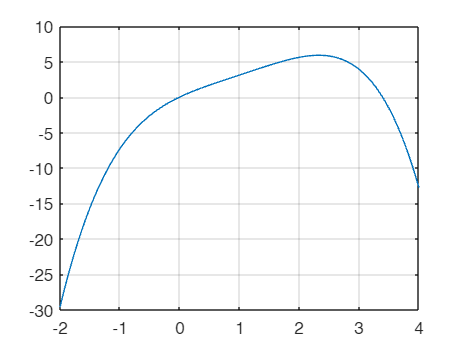

% Graphical
x = linspace(-2,4);
y = 4*x-1.8*x.^2+1.2*x.^3-0.3*x.^4;
plot(x,y);
grid
hold off;


f = @(x) 4*x-1.8*x^2+1.2*x^3-0.3*x^4;

% Find the max: gotta redo ftn
xl = -2; xu = 4; es = 1;
g = @(x) -1*(4*x-1.8*x^2+1.2*x^3-0.3*x^4);
[xmin,fx,ea,iter]=goldmin(f,xl,xu,es) % max

xmin = -1.9814

fx = -28.9497

ea = 0.9404

iter = 11

[xmax,gx,ea,iter]=goldmin(g,xl,xu,es) % max

xmax = 2.3282

gx = -5.8853

ea = 0.8004

iter = 11

fx_max = -1*gx

fx_max = 5.8853

#### fminbnd

% Get from the pic
% shows optimset

## Problem 7.3

Use parabolic interpolation to approx the min of f(x) = x^2/10-2*sin(x) with initial guesses x1 = 0, x2 = 1, x3 = 4

x1 = 0; x2 = 1; x3 = 4;
f = @(x) x^2/10-2*sin(x);
x4 = 1-0.5*((x2-x1)^2*(f(x2)-f(x3))-(x2-x3)^2*(f(x2)-f(x1)))...
    / ((x2-x1)*(f(x2)-f(x3))-(x2-x3)*(f(x2)-f(x1)))

x4 = 1.5055

f(x4)

ans = -1.7691

% continue, have to pick new x1 x2 x3: use x4 and 2 surrounding

#### Goldmin

%help goldmin
xl = 0; xu = 4;
[x,fx,ea,iter]=goldmin(f,xl,xu)

x = 1.4276

fx = -1.7757

ea = 9.3079e-05

iter = 30

#### fminbnd

% use Matlab builtin
[xmin, fval] = fminbnd(f,xl,xu)

xmin = 1.4275

fval = -1.7757

## Example 7.4 - Multidimensional

x: [-2 0] y: [0 3]

f(x1, x2) = 2+x1-x2+2*

g = @(x) 2+x(1)-x(2)+2*x(1)^2+2*x(1)*x(2)+x(2)^2;
[xmin, fval] = fminsearch(g, [-0.5 0.5])

xmin =    -1.0000    1.5000


fval = 0.7500

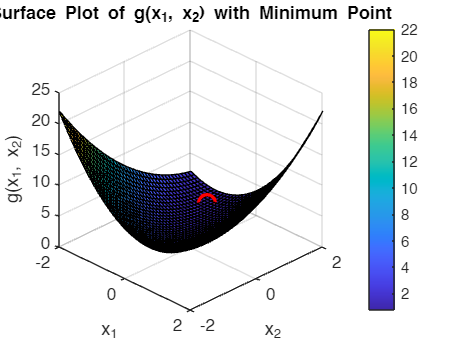


% Create a grid for plotting
[x1, x2] = meshgrid(-2:0.1:2, -2:0.1:2);

% Evaluate g(x1, x2) over the grid
G = 2 + x1 - x2 + 2*x1.^2 + 2*x1.*x2 + x2.^2;

% Plot 3D surface
figure;
surf(x1, x2, G);
hold on;
plot3(xmin(1), xmin(2), fval, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_1');
ylabel('x_2');
zlabel('g(x_1, x_2)');
title('Surface Plot of g(x_1, x_2) with Minimum Point');
colorbar;
grid on;
view(45, 30);

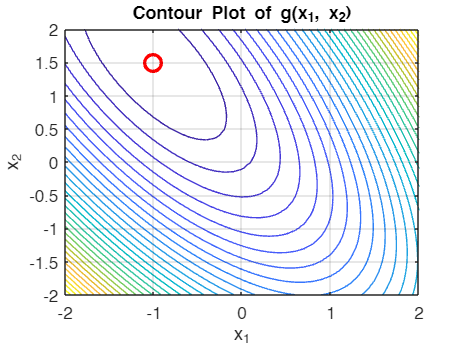


% Optional: Add a contour plot for clarity
figure;
contour(x1, x2, G, 30);
hold on;
plot(xmin(1), xmin(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x_1');
ylabel('x_2');
title('Contour Plot of g(x_1, x_2)');
grid on;
hold off;

## Problem 7.4

f(x) = -1.5x^6-2x^4+12x

a. Plot

b. 

## Problem 7.27

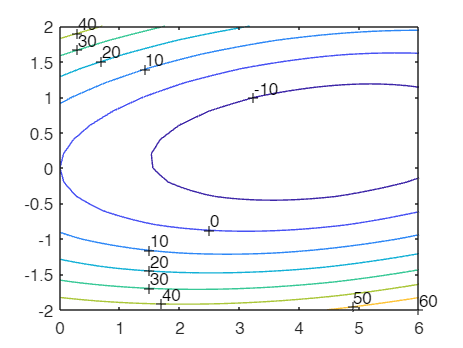

[x,y] = meshgrid(0:.2:6, -2:.2:2);
z = -8*x+x.^2+12*y.^2-2*x.*y;
cs = contour(x,y,z); clabel(cs);


f = @(x) -8*x+x.^2+12*y.^2-2*x.*y;
[xmin, fval] = fminsearch(f, [0 0])

Arrays have incompatible sizes for this operation.

Error in ICa_10_09_optimization>@(x)-8*x+x.^2+12*y.^2-2*x.*y (line 69)
f = @(x) -8*x+x.^2+12*y.^2-2*x.*y;

Error in fminsearch (line 209)
fv(:,1) = funfcn(x,varargin{:});



% x = 3.3333
% fval - -17.333
% FINISH
